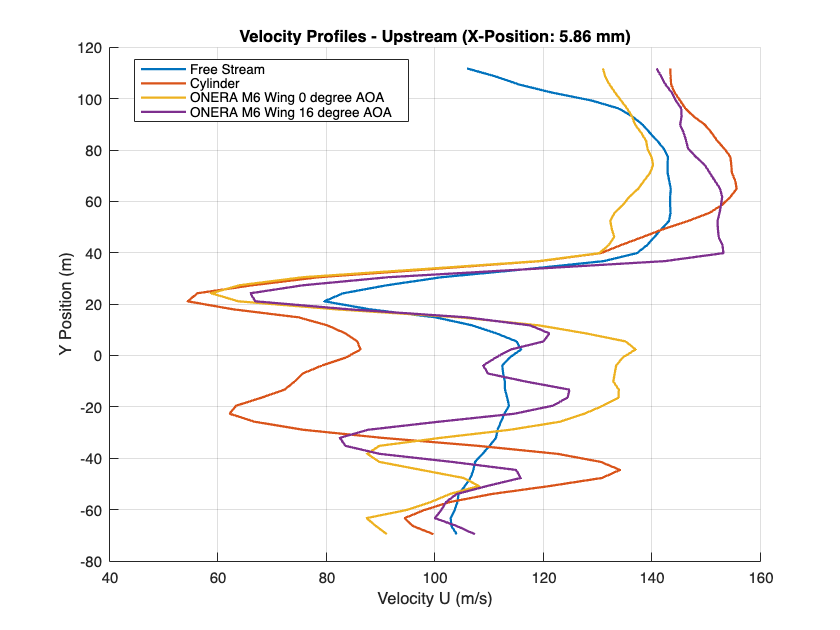

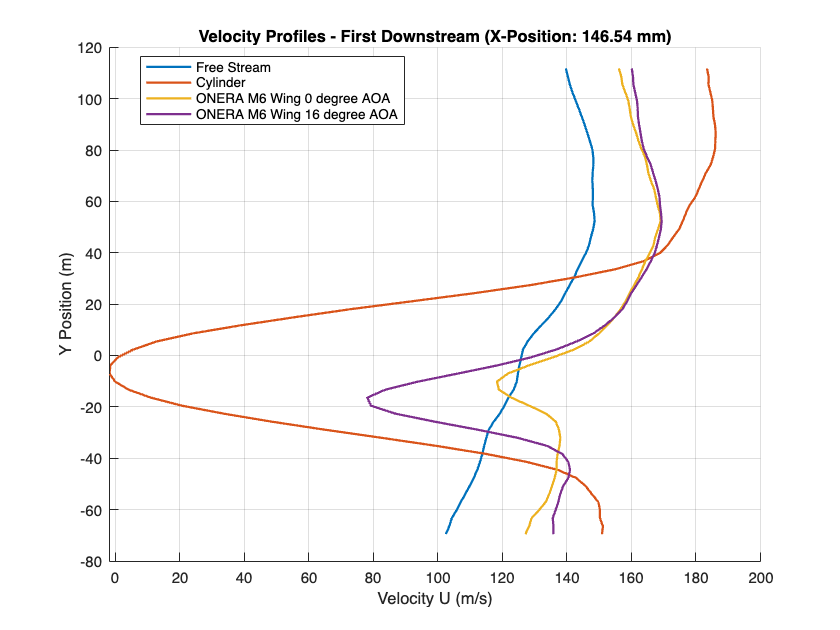

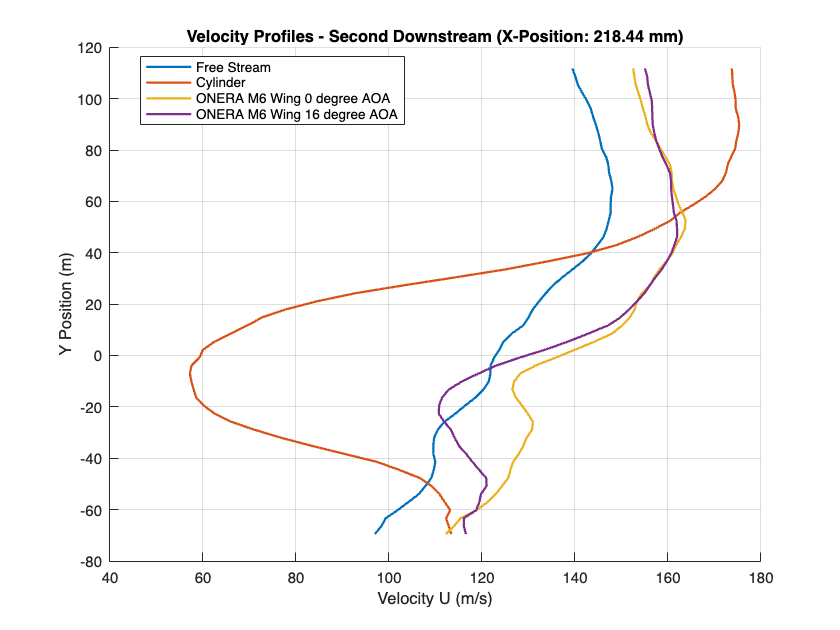

% Define folder path 
folders = {
'/Users/cameron8743/Desktop/Water_Tunnel_Data/Baseline(freestream)';
'/Users/cameron8743/Desktop/Water_Tunnel_Data/Cylinder/Cylinder';
'/Users/cameron8743/Desktop/Water_Tunnel_Data/Swept_0aoa/Swept_0aoa';
'/Users/cameron8743/Desktop/Water_Tunnel_Data/Swept_16aoa/Swept_16aoa'};

% Define names dynamically based on folder paths
folderTitles = cell(size(folders)); % Initialize a cell array for titles

for Idx = 1:numel(folders)
    folderPath = folders{Idx};
    if contains(folderPath, 'Cylinder', 'IgnoreCase', true)
        folderTitles{Idx} = 'Cylinder';
    elseif contains(folderPath, 'Swept_0aoa', 'IgnoreCase', true)
        folderTitles{Idx} = 'ONERA M6 Wing 0 degree AOA';
    elseif contains(folderPath, 'Swept_16aoa', 'IgnoreCase', true)
        folderTitles{Idx} = 'ONERA M6 Wing 16 degree AOA';
    else
        folderTitles{Idx} = 'Free Stream';
    end
end

% Mean and RMS Fields Calculation 
meanFieldsX = cell(1, numel(folders));
meanFieldsY = cell(1, numel(folders));
RMSFieldsX  = cell(1, numel(folders));
RMSFieldsY  = cell(1, numel(folders));

% Loop over each test folder
for Idx = 1:numel(folders)
    folderPath = folders{Idx};
    matFiles = dir(fullfile(folderPath, '*.mat'));  
    
    % Load position data from the first file in the folder
    if ~isempty(matFiles)
        firstFile = load(fullfile(folderPath, matFiles(1).name));
        positionX = firstFile.positionX;  % [mm]
        positionY = firstFile.positionY;  % [mm]
    else
        error(['No .mat files found in folder: ', folderPath]);
    end
    
    % Lists to store vector data for averaging
    vectorsX_all = [];
    vectorsY_all = [];
    
    % Loop through each .mat file in folder
    for fileIdx = 1:numel(matFiles)
        data = load(fullfile(folderPath, matFiles(fileIdx).name));
        vectorsX = data.vectorsX;  % [mm/s]
        vectorsY = data.vectorsY;  % [mm/s]
        vectorsX_all = cat(3, vectorsX_all, vectorsX);
        vectorsY_all = cat(3, vectorsY_all, vectorsY);
    end
    
    % Calculate mean fields and ignore NaNs
    meanVectorX = nanmean(vectorsX_all, 3);
    meanVectorY = nanmean(vectorsY_all, 3);
    
    % Calculate fluctuations 
    fluctuationsX = bsxfun(@minus, vectorsX_all, meanVectorX);
    fluctuationsY = bsxfun(@minus, vectorsY_all, meanVectorY);
    
    % Set NaN values in fluctuations to zero to exclude them from RMS 
    fluctuationsX(isnan(fluctuationsX)) = 0;
    fluctuationsY(isnan(fluctuationsY)) = 0;
    
    % Compute RMS  
    RMSVectorX = sqrt(nanmean(fluctuationsX.^2, 3));
    RMSVectorY = sqrt(nanmean(fluctuationsY.^2, 3));
    
    % Store results
    meanFieldsX{Idx} = meanVectorX;
    meanFieldsY{Idx} = meanVectorY;
    RMSFieldsX{Idx} = RMSVectorX;
    RMSFieldsY{Idx} = RMSVectorY;
end

% ----------------------------------------------- %
%              Velocity Profiles                  %
% ----------------------------------------------- %

% Indices for upstream and downstream locations for each test
inflowIndices = [5, 5, 5, 5]; 
downstreamIndices = [50, 50, 50, 50]; 
secondDownstreamIndices = [73, 73, 73, 73];  

% Color map 
colors = lines(4);  

% Loop over each location type 
for locationType = 1:3
    % Create a new figure for each location type
    figure;
    hold on;
    
    % Set the title based on location type
    switch locationType
        case 1
            locationName = 'Upstream';
            indices = inflowIndices;
        case 2
            locationName = 'First Downstream';
            indices = downstreamIndices;
        case 3
            locationName = 'Second Downstream';
            indices = secondDownstreamIndices;
    end
    
    % Plot velocity profiles for each test case at the specified location
    for Idx = 1:numel(folders)
        % Load position data and mean velocity fields for the current test case
        meanVelocityX = meanFieldsX{Idx};  % X-component of mean velocity (U)
        
        % Determine Y positions based on the size of meanVelocityX rows
        if length(positionY) == size(meanVelocityX, 1)
            yPositions = positionY;
        else
            % Interpolate positionY to match meanVelocityX row size
            warning('Interpolating positionY to match meanVelocityX row size.');
            yPositions = linspace(min(positionY), max(positionY), size(meanVelocityX, 1))';
        end
        
        % Get the index for the location based on the type 
        profileIdx = indices(Idx);
        
        % Skip if the index is out of bounds
        if isnan(profileIdx) || profileIdx > size(meanVelocityX, 2)
            warning(['Skipping test case ', num2str(Idx), ' due to invalid profile index.']);
            continue;
        end
        
        % Extract the x-position for the velocity profile
        xPosition = positionX(profileIdx); % Get the x position for the current profile
        
        % Extract the velocity profile at the specified location
        profile = meanVelocityX(:, profileIdx);
        
        % Smooth the profile data
        smoothedProfile = smoothdata(profile, 'movmean', 5); % 5-point moving average smoothing
                
        % Plot the smoothed profile 
        plot(smoothedProfile, yPositions, 'Color', colors(Idx, :), 'LineWidth', 1.5, ...
             'DisplayName', folderTitles{Idx});
    end
    
    % Add labels, title, and legend
    xlabel('Velocity U (m/s)');
    ylabel('Y Position (m)');
    title(sprintf('Velocity Profiles - %s (X-Position: %.2f mm)', locationName, xPosition));
    legend('Location', 'best');
    grid on;
    hold off;
    drawnow;
end

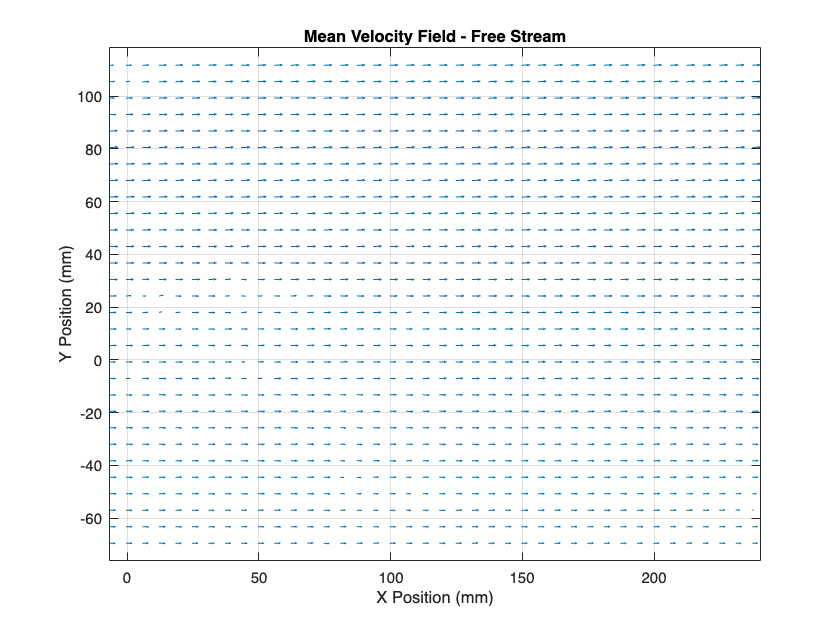

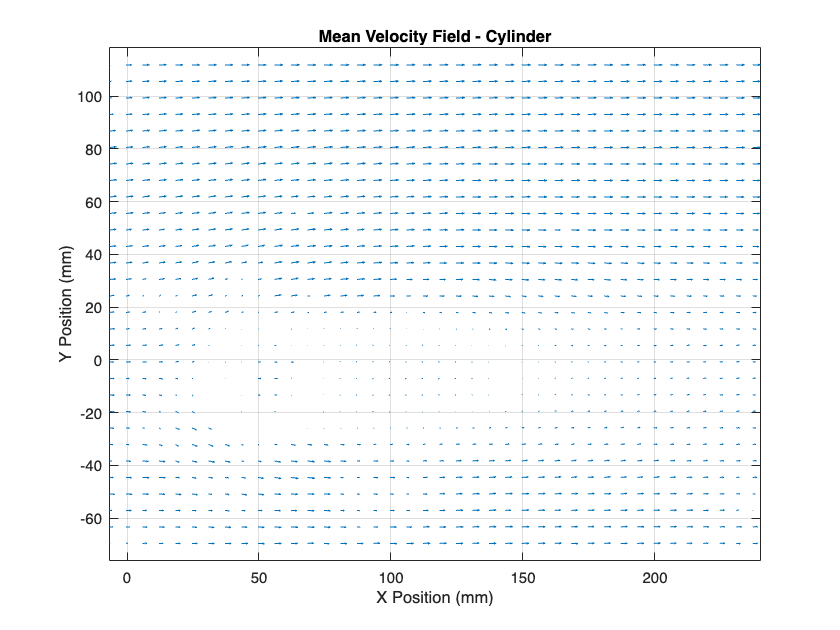

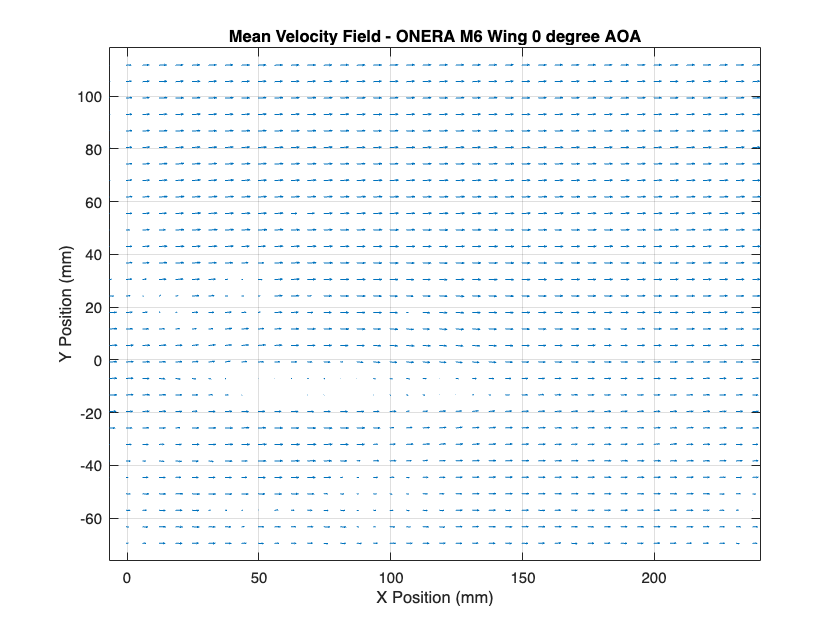

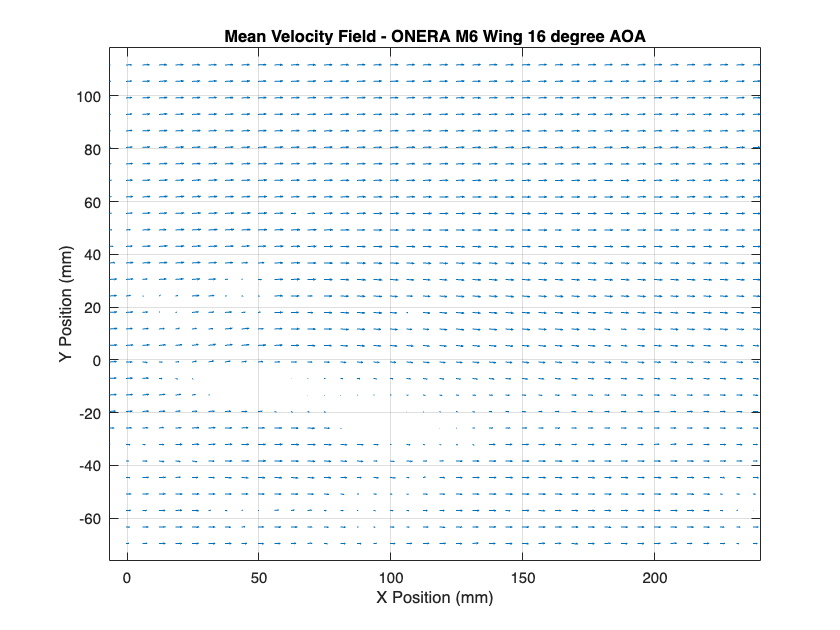



% ----------------------------------------------- %
%        Mean Velocity Field Quiver Plots         %
% ----------------------------------------------- %

dsFactor = 2;  
scaleFactor = 0.4;  

for Idx = 1:numel(folders)
    meanU = meanFieldsX{Idx}(1:dsFactor:end, 1:dsFactor:end);
    meanV = meanFieldsY{Idx}(1:dsFactor:end, 1:dsFactor:end);
    posX = positionX(1:dsFactor:end);
    posY = positionY(1:dsFactor:end);
    
    % Create figure for each test case
    figure;
    quiver(posX, posY, meanU, meanV, 'AutoScale', 'on', 'AutoScaleFactor', scaleFactor);
    
    % Use specific test name for the title
    title(['Mean Velocity Field - ', folderTitles{Idx}]);
    xlabel('X Position (mm)');
    ylabel('Y Position (mm)');
    axis equal;
    grid on;
end

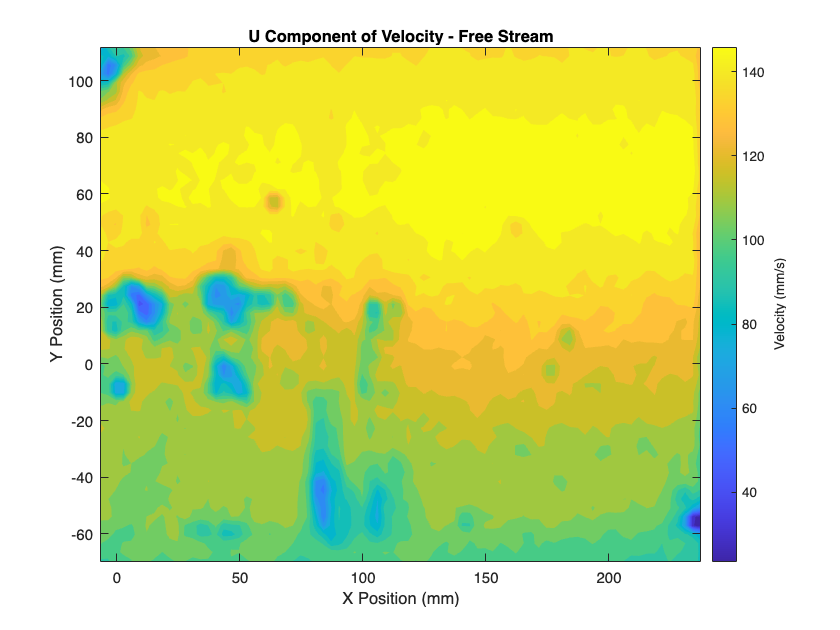

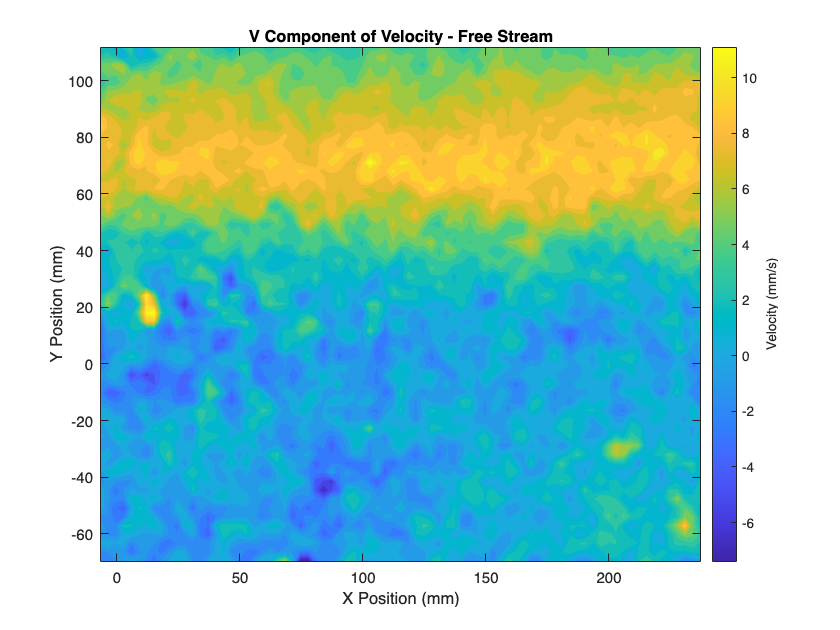

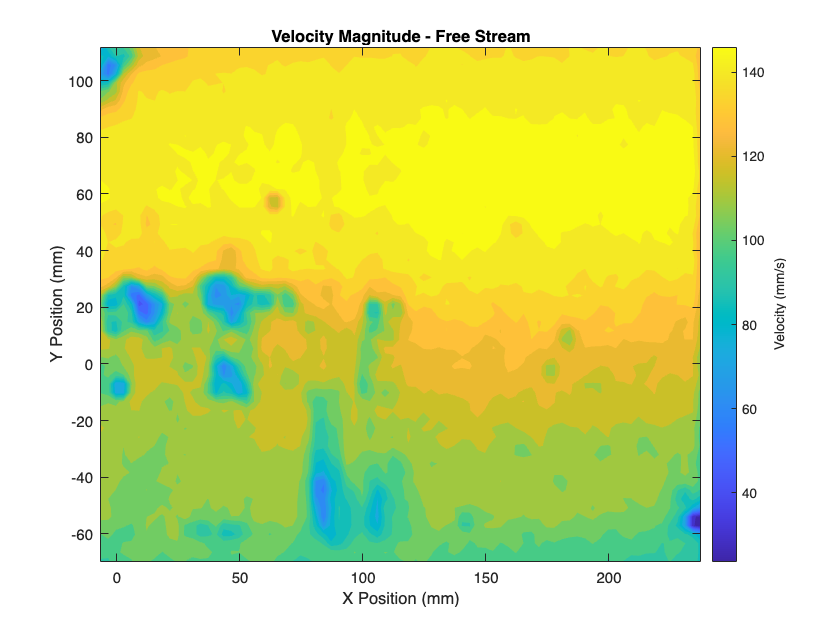

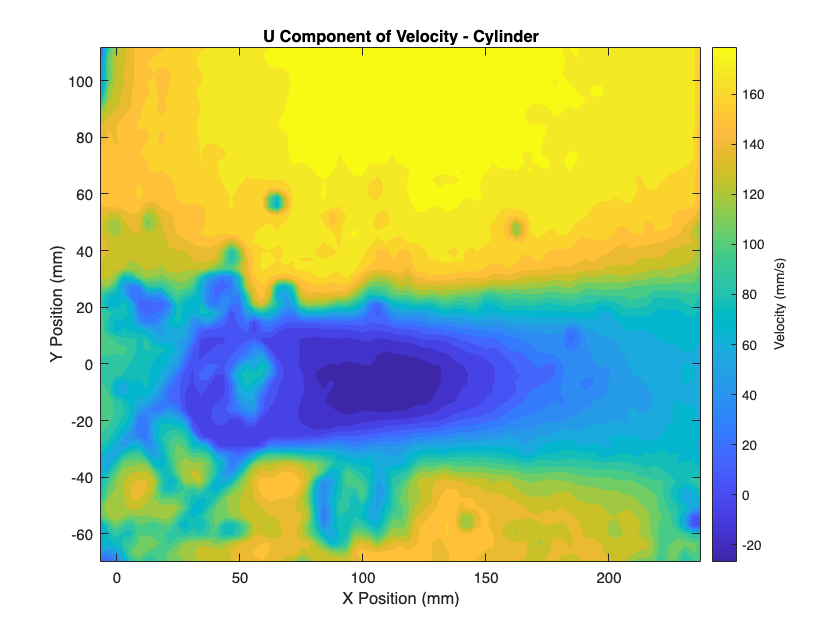

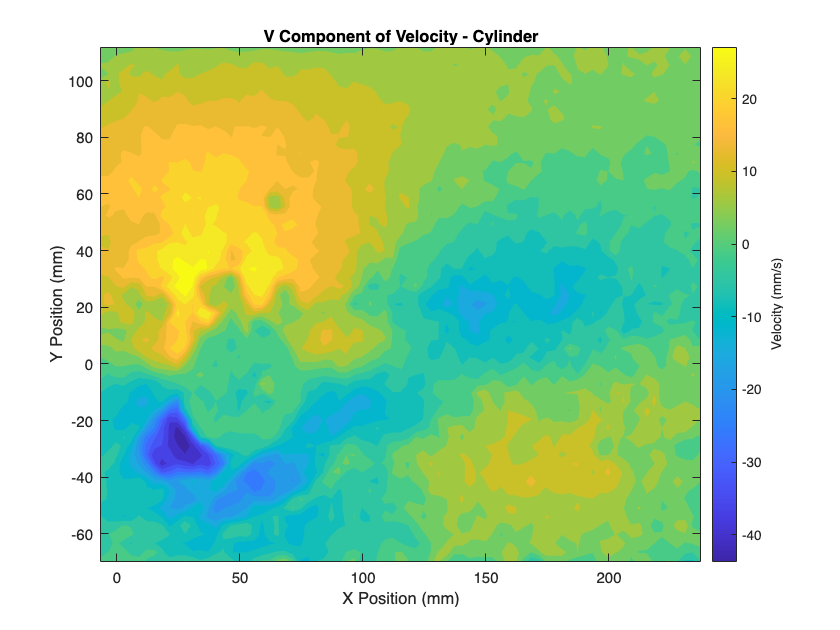

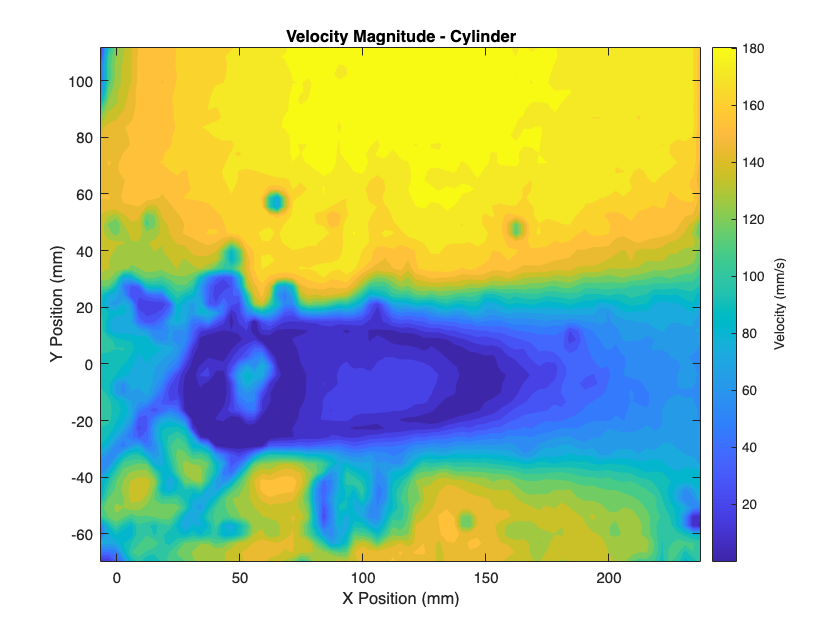

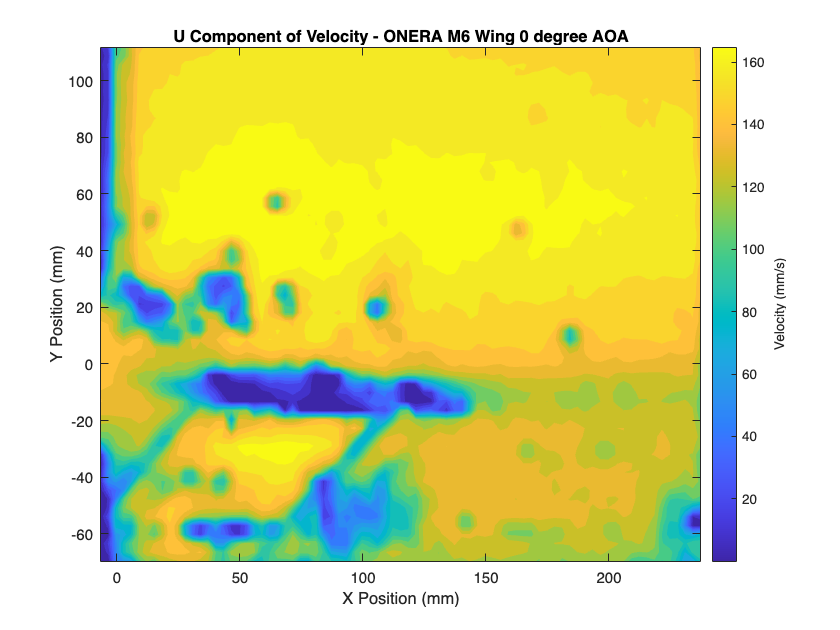

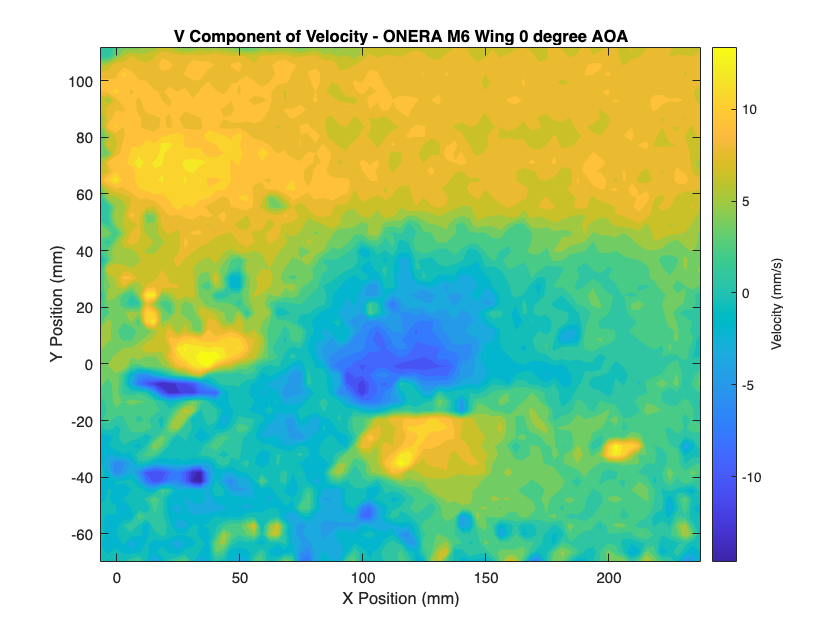


% ----------------------------------------------- %
%                   Contour Plots                 %
% ----------------------------------------------- %

for Idx = 1:numel(folders)
    % Retrieve mean fields for the current test 
    meanU = meanFieldsX{Idx};
    meanV = meanFieldsY{Idx};
    
    % Calculate the velocity magnitude 
    meanVmag = sqrt(meanU.^2 + meanV.^2);
    
    % Create meshgrid 
    [X, Y] = meshgrid(positionX, positionY);
    
    % Plot contour for U component
    figure;
    contourf(X, Y, meanU, 20, 'LineColor', 'none'); 
    c = colorbar;
    c.Label.String = 'Velocity (mm/s)';
    title(['U Component of Velocity - ', folderTitles{Idx}]);
    xlabel('X Position (mm)');
    ylabel('Y Position (mm)');
    
    % Plot contour for V component
    figure;
    contourf(X, Y, meanV, 20, 'LineColor', 'none'); 
    c = colorbar;
    c.Label.String = 'Velocity (mm/s)';
    title(['V Component of Velocity - ', folderTitles{Idx}]);
    xlabel('X Position (mm)');
    ylabel('Y Position (mm)');
    
    % Plot contour for velocity magnitude
    figure;
    contourf(X, Y, meanVmag, 20, 'LineColor', 'none'); 
    c = colorbar;
    c.Label.String = 'Velocity (mm/s)';
    title(['Velocity Magnitude - ', folderTitles{Idx}]);
    xlabel('X Position (mm)');
    ylabel('Y Position (mm)');
end

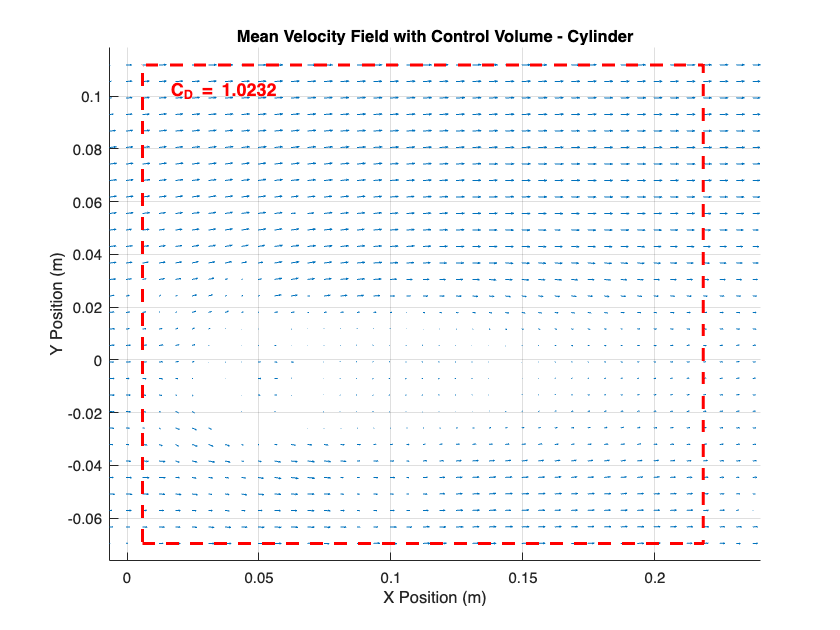

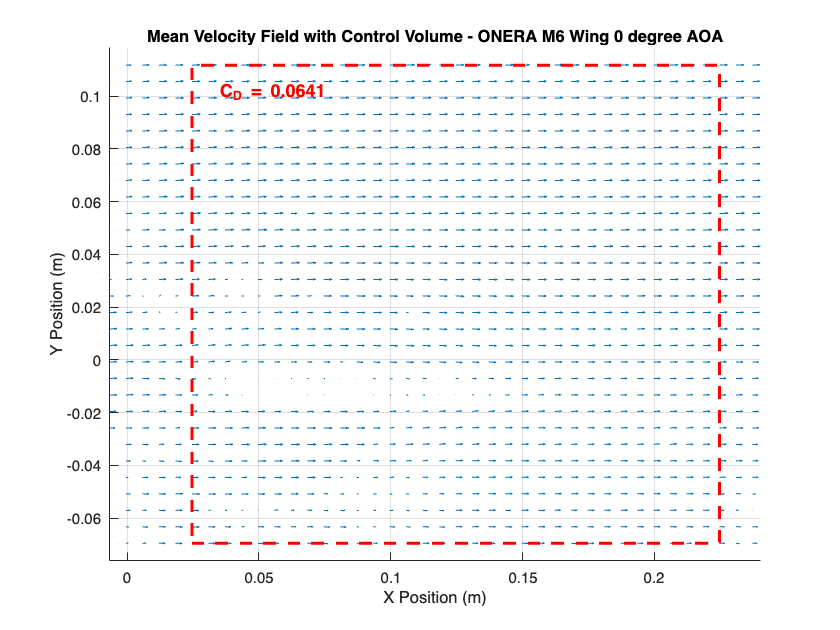

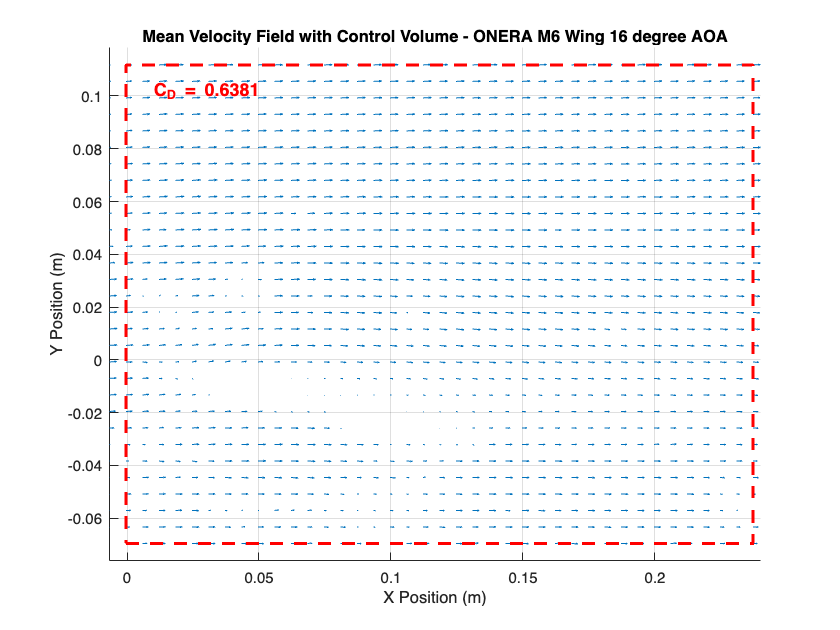


% ----------------------------------------------- %
%   Drag Coeficient From Control Volume Analysis  %
% ----------------------------------------------- %

% === Constants and Parameters ===
density = 1000;             % [kg/m^3]
freestreamVelocity = 0.23;  % [m/s]
D_cylinder = 0.0381;        % [m]
L_cylinder = 0.1524;        % [m]
root_chord = 0.1016;        % [m]
tip_chord = 0.05766;        % [m]
span = 0.1524;              % [m]
average_chord = (root_chord + tip_chord) / 2; % [m]

% Define specific inflow and downstream indices for each test 
inflowIndices = [NaN, 5, 11, 3];        % Set inflow indices, NaN for freestream
downstreamIndices = [NaN, 73, 75, 79];  % Set downstream indices

% Initialize array to store drag coefficients
dragCoefficients = zeros(1, numel(folders) - 1);

% Drag Coefficient Calculation 
for Idx = 2:numel(folders)
    folderPath = folders{Idx};
    matFiles = dir(fullfile(folderPath, '*.mat'));  % Find all .mat files in the folder
    
    % Load position data
    if ~isempty(matFiles)
        firstFile = load(fullfile(folderPath, matFiles(1).name));
        positionX = firstFile.positionX * 1e-3; % [m] 
        positionY = firstFile.positionY * 1e-3; % [m]
    else
        error(['No .mat files found in folder: ', folderPath]);
    end
    
    % Stack velocity data
    vectorsX_all = [];
    for fileIdx = 1:numel(matFiles)
        data = load(fullfile(folderPath, matFiles(fileIdx).name));
        vectorsX_all = cat(3, vectorsX_all, data.vectorsX * 1e-3); % Convert to [m/s]
    end
    
    % Calculate mean velocity fields
    meanVectorX = nanmean(vectorsX_all, 3);

    % Set inflow and downstream indices
    inflowIdx = inflowIndices(Idx);
    downstreamIdx = downstreamIndices(Idx);

    % Ensure valid indices
    if isnan(inflowIdx) || isnan(downstreamIdx)
        warning('Skipping test %d due to invalid indices.', Idx);
        continue;
    end
    
    % Calculate spacing in y for integration
    dy = abs(positionY(2) - positionY(1));  
    
    % Calculate inflow and outflow momentum flux
    inflowProfile = meanVectorX(:, inflowIdx);
    outflowProfile = meanVectorX(:, downstreamIdx);

    inflowMomentum = density * sum((freestreamVelocity - inflowProfile).^2 * dy);
    outflowMomentum = density * sum((freestreamVelocity - outflowProfile).^2 * dy);

    % Calculate drag force
    dragForce = inflowMomentum - outflowMomentum;

    % Calculate reference area
    if Idx == 2
        refArea = D_cylinder * L_cylinder; % Cylinder
    else
        refArea = average_chord * span;     % Wing
    end
    
    % Calculate drag coefficient
    dragCoefficients(Idx - 1) = dragForce / (0.5 * density * freestreamVelocity^2 * refArea);
end

% Plot Control Volume 
dsFactor = 2;
scaleFactor = 0.4;

for Idx = 2:numel(folders)
    % Load mean velocity fields
    meanU = meanFieldsX{Idx}(1:dsFactor:end, 1:dsFactor:end);
    meanV = meanFieldsY{Idx}(1:dsFactor:end, 1:dsFactor:end);
    posX = positionX(1:dsFactor:end);
    posY = positionY(1:dsFactor:end);

    % Create figure
    figure;
    hold on;
    quiver(posX, posY, meanU, meanV, 'AutoScale', 'on', 'AutoScaleFactor', scaleFactor);

    % Define control volume
    inflowIdx = inflowIndices(Idx);
    downstreamIdx = downstreamIndices(Idx);

    if ~isnan(inflowIdx) && ~isnan(downstreamIdx)
        x_left = positionX(inflowIdx);
        x_right = positionX(downstreamIdx);
        y_bottom = min(positionY);
        y_top = max(positionY);
        
        % Plot control volume
        plot([x_left x_right x_right x_left x_left], ...
             [y_bottom y_bottom y_top y_top y_bottom], 'r--', 'LineWidth', 2);

        % Annotate drag coefficient
        dragText = sprintf('C_D = %.4f', dragCoefficients(Idx - 1));
        text(x_left + 0.01, y_top - 0.01, dragText, 'Color', 'red', ...
             'FontSize', 12, 'FontWeight', 'bold');
    end

    % Title and labels
    title(['Mean Velocity Field with Control Volume - ', folderTitles{Idx}]);
    xlabel('X Position (m)');
    ylabel('Y Position (m)');
    axis equal;
    grid on;
    hold off;

end